# **Fundamentals of Robotics**

**Introduction to Robotics Modeling and Control**

clear;
close all;
format compact;

## Forward Kinematics: Denavit-Hartenberg Convention

#### EXAMPLE 1. Two Link Planar Robot Manipulator

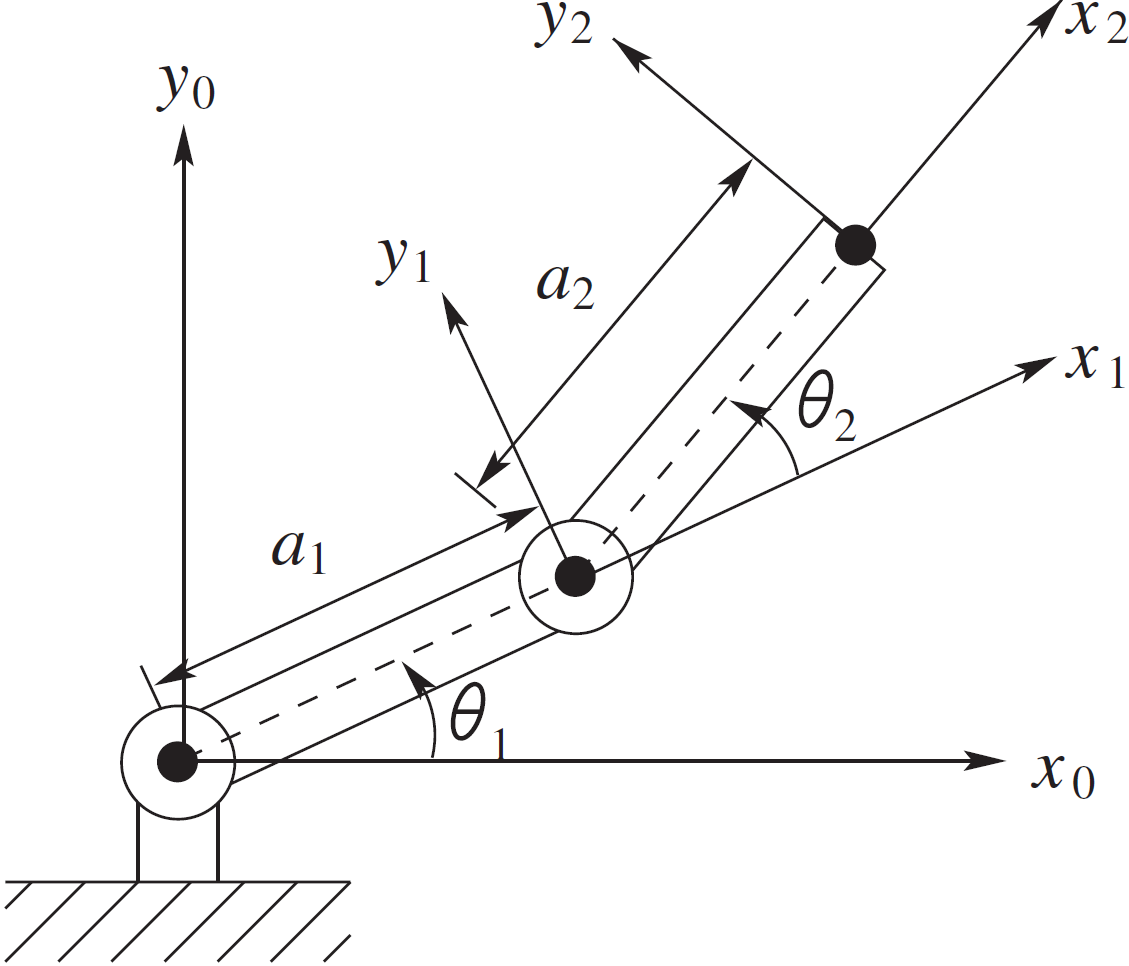

**DH Parameters Table:**

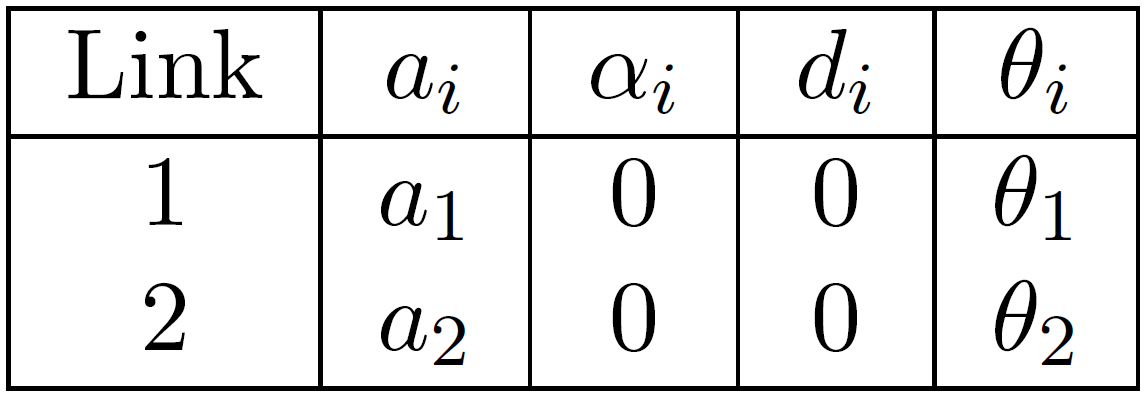

link1 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link1');   % LINK1:    d=0, a=1, alpha=0, *theta1 + offset=0
link2 = RevoluteLink(0, 1.25, 0, 0, 'name', 'link2');   % LINK2:    d=0, a=1, alpha=0, *theta2 + offset=0

% Serial Link Manipulator
% 2-DOF (RR) Planar Robot
robot = SerialLinkManipulator([link1, link2], 'name', '2-DOF RR Planar Robot');

theta1 =-45;
theta2 =45;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).theta = deg2rad(theta2);

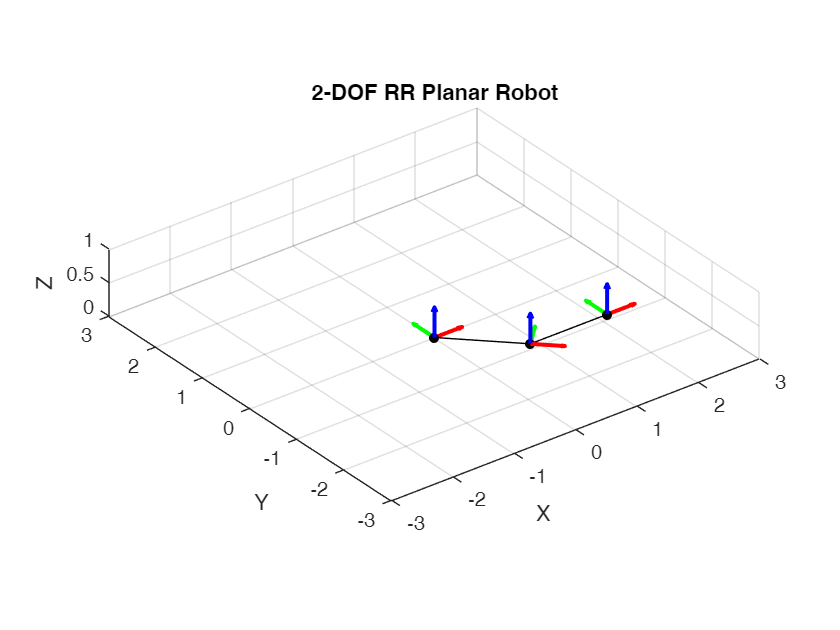

figure;
hold on;
plot([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.5, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-3, 3]); 
ylim([-3, 3]); 
zlim([0, 1]);

#### EXAMPLE 2. Three-Link Cylindrical Manipulator

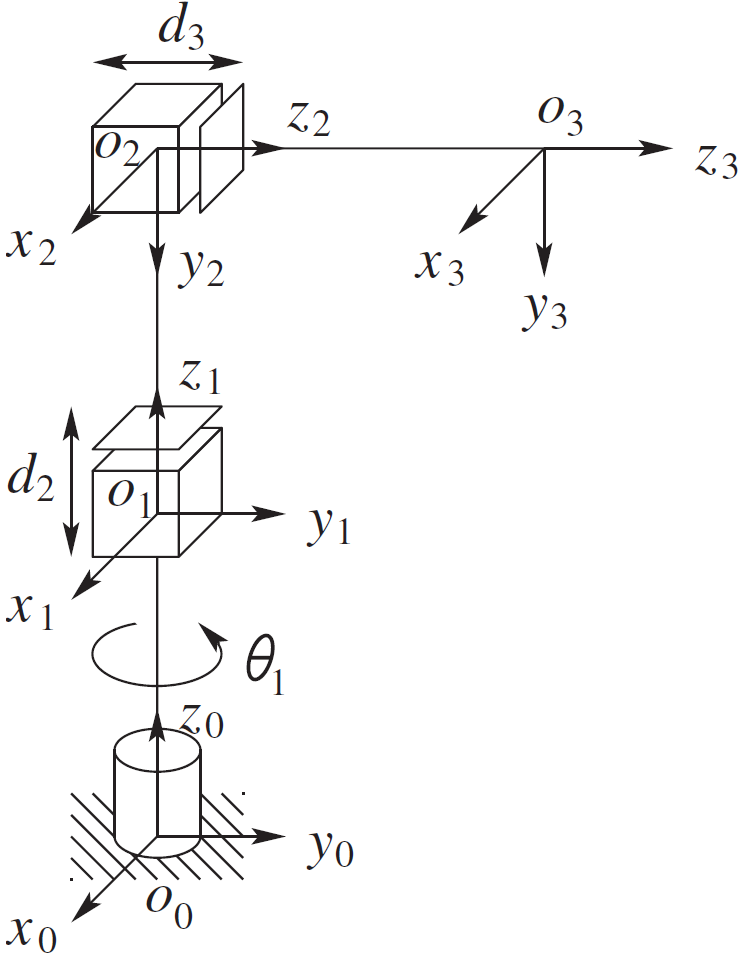

**DH Parameters Table:**

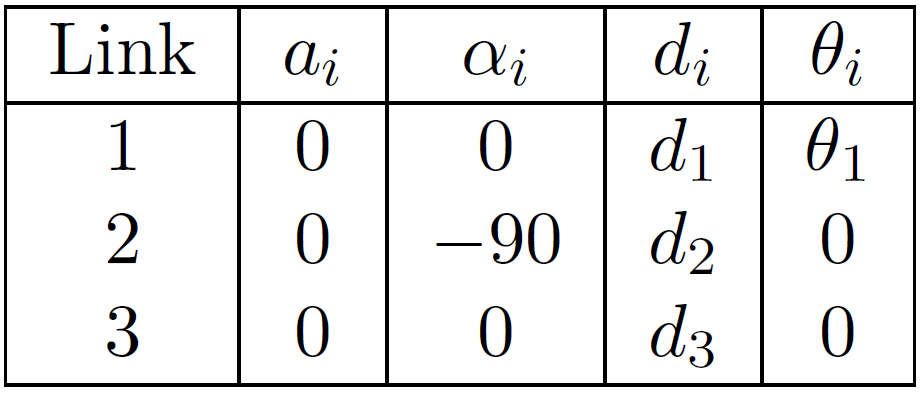

l1 = Link([0, 1, 0, 0]);
l2 = Link([0, 0, 0, -pi/2], 'type', 'prismatic');
l3 = Link([0, 0, 0, 0], 'type', 'prismatic');

% Three-Link Cylindrical Manipulator
robot = SerialLinkManipulator([l1, l2, l3], 'name', '3-DOF RPP Cylindrical Manipulator');

theta1 =30;
d2 =1.5;
d3 =1;

robot.links(1).theta = deg2rad(theta1);
robot.links(2).d = d2;
robot.links(3).d = d3;

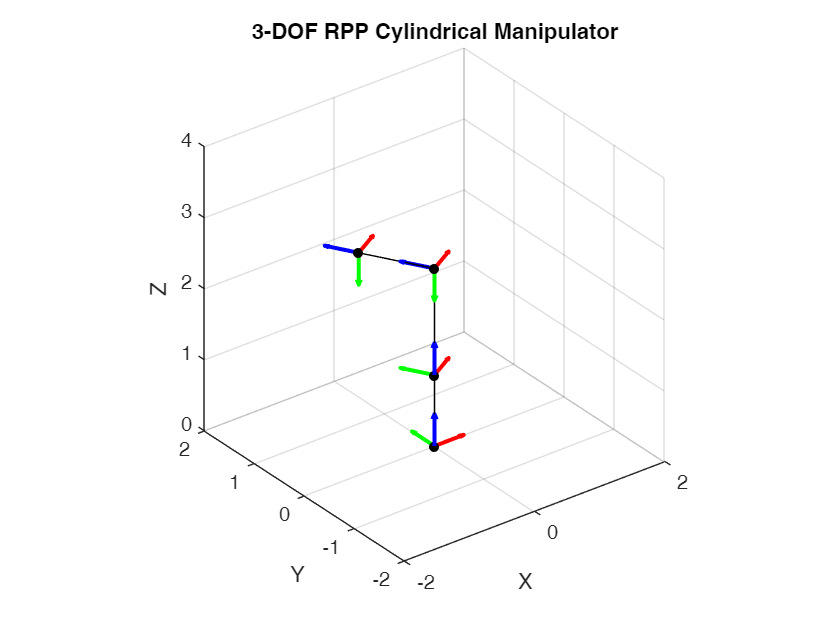

figure;
hold on;
plot3([robot.jointPose(1,:), robot.x(1)], [robot.jointPose(2,:), robot.x(2)], [robot.jointPose(3,:), robot.x(3)], 'k-');
plotHomogFrames(robot.homogtf, 'Scale', 0.5, 'ArrowStyle', 'arrow'); 

title(robot.name);
xlim([-2, 2]); 
ylim([-2, 2]); 
zlim([0, 4]);